# Gravitational field

clear, clc, close all
set_demo_defaults
R_e = 6.371e6; % [m] radius of the Earth
M_e =  5.9722e24; % [kg] Mass of the Earth
rho_ave = 5520;  % [m] ave. density of the Earth
Grav_const = 6.6743e-11; % [m^3/(kg s^2)] Gravitational constant

## 1. Gravity basics

### 1.1 Gravitational field and potential

The gravitational field $\mathbf{g}$ is a vector field as the negative gradient of the gravitational potential, $\Phi$, as

$\mathbf{g} = -\nabla \Phi$.

Gauss's flux theorem for gravity requires that 


$$\oint_{\partial\Omega} \mathbf{g}\cdot\hat{\mathbf{n}}\, \mathrm{d}A = -4\pi G M$$


where $G$ is the universal gravitational constant and $M=\int_{\Omega}\rho\,\mathrm{d}V$is the enclosed mass.

Using the Divergence Theorem we convert the surface integral into a volume integral and obtain Poisson's equation for gravity

$\nabla^2\Phi = 4\pi G\rho$.

This gravitational 

### 1.2 Point source


$$g = \frac{GM}{r^2}$$


grav_fild_point = @(r) - Grav_const*M_e./(r.^2);

## 2. Gravitational field of the Earth

Set up the grid, operators and boundary conditions

Grid.xmin = 0; Grid.xmax = 3*R_e; Grid.Nx = 1e3;
Grid.geom = 'spherical_r';
Grid = build_grid(Grid);
[D,G,~,I,M] = build_ops(Grid);

L = D*G;
flux = @(Phi) -G*Phi;
res = @(Phi,cell) L(cell,:)*Phi -fs(cell);

% Boundary conditions
BC.dof_dir = Grid.dof_xmax;
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g = 0;

BC.dof_neu = [];
BC.dof_f_neu = [];
BC.qb = [];

[B,N,fn] = build_bnd(BC,Grid,I);

### 2.1 Uniform density

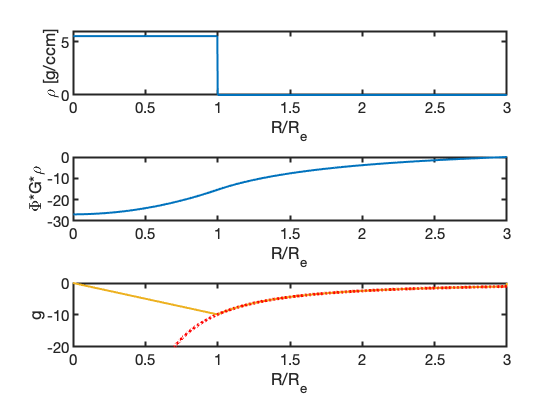

rho_hom = rho_ave*ones(Grid.N,1).*(Grid.xc<=R_e);
fs = 4*pi*rho_hom*Grav_const;
res = @(Phi,cell) L(cell,:)*Phi -fs(cell);
% solve for potential and field
Phi = solve_lbvp(L,fs,B,BC.g,N);
grav_field_hom = comp_flux_gen(flux,res,Phi,Grid,BC);

subplot 311
plot(Grid.xc/R_e,rho_hom/1e3)
ylim([0 6])
xlabel 'R/R_e', ylabel '\rho [g/ccm]'

subplot 312
plot(Grid.xc/R_e,Phi*Grav_const*rho_ave)
ylim([-30 0])
xlabel 'R/R_e', ylabel '\Phi*G*\rho'


subplot 313
plot(Grid.xf/R_e,grav_field_hom), hold on
plot(Grid.xc/R_e,grav_fild_point(Grid.xc),'r:')
ylim([-20 0])
xlabel 'R/R_e', ylabel 'g'

### 2.2 Heterogeneous density

In 1936 Inge Lehman discovered that the earth has a core!

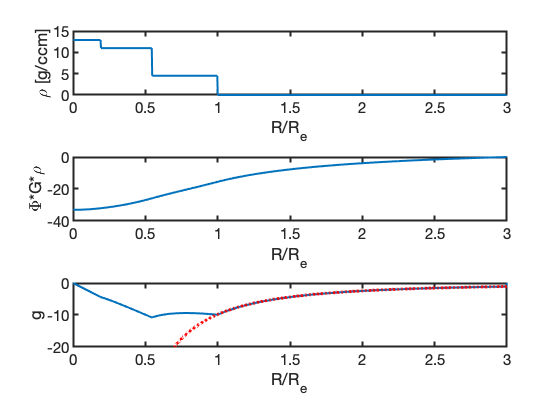

R_inner = 1.220e6;
R_outer = 3.485e6;
rho_inner = 12900;
rho_outer = 11000;
rho_mantle = 4500;
rho_het = rho_mantle*ones(Grid.N,1).*(Grid.xc<=R_e);
rho_het(Grid.xc<=R_outer) = rho_outer;
rho_het(Grid.xc<=R_inner) = rho_inner;

fs_het = 4*pi*rho_het*Grav_const;
res_het = @(Phi,cell) L(cell,:)*Phi -fs_het(cell);

% solve for potential and field
Phi_het = solve_lbvp(L,fs_het,B,BC.g,N);
grav_field_het = comp_flux_gen(flux,res_het,Phi_het,Grid,BC);

figure
subplot 311
plot(Grid.xc/R_e,rho_het/1e3)
xlim([0 3]),ylim([0 15])
xlabel 'R/R_e', ylabel '\rho [g/ccm]'

subplot 312
plot(Grid.xc/R_e,Phi_het*Grav_const*rho_ave)
% ylim([-30 0])
xlabel 'R/R_e', ylabel '\Phi*G*\rho'


subplot 313
plot(Grid.xf/R_e,grav_field_het), hold on
plot(Grid.xc/R_e,grav_fild_point(Grid.xc),'r:')
ylim([-20 0])
xlabel 'R/R_e', ylabel 'g'